
% This script demonstrates the end to end pipeline for classifying human 
% activities (Sitting, Standing, Walking, Cycling, etc.).
% Author: Abdulrehman Bin Yasin
% Repository: https://github.com/bcap52/EdgeHAR-Efficient-Human-Activity-Recognition-Using-IMU-Sensors/tree/main

%% 1. Setup Environment
clear; clc; close all;
addpath(genpath(pwd));

%% 2. Load Processed Data (Training & Testing)
%IMPORTANT: If you do not want to use already processed data available at 'Data/processedData.mat, Ensure you have downloaded the 'Data' folder 
% from the links provided in the GitHub README and placed them in this directory, otherwise the code will thrown an error

%for testing you need to download the datasets at the provided link on
%github and in the training datasets folder
processedFile = fullfile('data', 'processed', 'ProcessedData.mat');

if isfile(processedFile)
    fprintf('Loading preprocessed datasets from ...\n');
    load(processedFile, 'Dataset_50HZ_Limited_Train_19974_eachclass', 'Dataset_50HZ_Limited_Test_Final','mobile_features');
else
    fprintf('Processed file missing. Generating from raw CSVs...\n');
    fprintf('This process requires the "Data" and "Testing Datasets" folders.\n');
    
    % Call the DataPreparation function to generate tables
[Dataset_50HZ_Limited_Train_19974_eachclass, Dataset_50HZ_Limited_Test_Final, mobile_features] = Data_PreProcessing_FeatureEngineering();
    % Save for future runs to save time

Processed file missing. Generating from raw CSVs...


This process requires the "Data" and "Testing Datasets" folders.


Processing Training Data from: Data
Processing Testing Data...
Data Preparation Complete.
Processing MATLAB Mobile Data from: Data/Mobile Recordings
Data Preparation Complete.


    if ~isfolder('data/processed'), mkdir('data/processed'); end
    save(processedFile, 'Dataset_50HZ_Limited_Train_19974_eachclass', 'Dataset_50HZ_Limited_Test_Final','mobile_features');
end


fprintf('Loaded Training Data: %d rows\n', height(Dataset_50HZ_Limited_Train_19974_eachclass));

Loaded Training Data: 1758 rows


fprintf('Loaded Testing Data:  %d rows\n', height(Dataset_50HZ_Limited_Test_Final));

Loaded Testing Data:  2952 rows



%% 3. Load or Train Model
modelFile = fullfile('models', 'trainedModel.mat');

if isfile(modelFile) 
    fprintf('\nLoading pretrained model from: %s ...\n', modelFile);
    modelStruct = load(modelFile, 'trainedModel');
    myModel = modelStruct.trainedModel;
    fprintf('Model loaded successfully.\n');


  %This would train a new model using src/trainedClassifier.m, in case you do not have models/trainedModel.mat in your directory


else 
    fprintf('\n No pre trained model found. Training new model...\n');
    fprintf('Training.....This may take a moment.\n');
    
    % Training the model using the imported function
    [myModel, accuracy] = trainClassifier(Dataset_50HZ_Limited_Train_19974_eachclass);
    
    % Saving it
    if ~isfolder('models'), mkdir('models'); end
    save(modelFile, 'myModel');
    fprintf('New model trained and saved to %s.\n', modelFile);
end


Loading pretrained model from: models\trainedModel.mat ...


Model loaded successfully.



%% 4. Performance Evaluation (Train vs Test)

% A) Training Accuracy 
pred_train = myModel.predictFcn(Dataset_50HZ_Limited_Train_19974_eachclass);
acc_train = sum(pred_train == Dataset_50HZ_Limited_Train_19974_eachclass.label) / height(Dataset_50HZ_Limited_Train_19974_eachclass);

% B) Testing Accuracy (Generalization on Unseen Data)
pred_test = myModel.predictFcn(Dataset_50HZ_Limited_Test_Final);
acc_test = sum(pred_test == Dataset_50HZ_Limited_Test_Final.label) / height(Dataset_50HZ_Limited_Test_Final);

% Display Metrics

fprintf('PERFORMANCE METRICS\n');

PERFORMANCE METRICS



fprintf('Training Accuracy: %.2f%%\n', acc_train * 100);

Training Accuracy: 91.18%


fprintf('Testing Accuracy:  %.2f%%\n', acc_test * 100);

Testing Accuracy:  93.22%


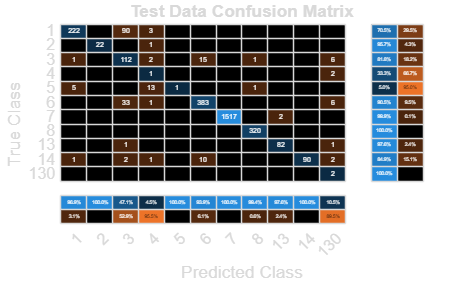


% Note: To view detailed visualizations and training history, open the 
% 'Classification Learner' app in MATLAB and import the session file:
% src/Classification_LearnerApp_Workspace.mat

%visualization of confusion matrix
figure('Name', 'Confusion Matrix', 'Color', 'w');
cm = confusionchart(Dataset_50HZ_Limited_Test_Final.label, pred_test);
cm.Title = 'Test Data Confusion Matrix';
cm.RowSummary = 'row-normalized'; 
cm.ColumnSummary = 'column-normalized'; % Shows Precision per class

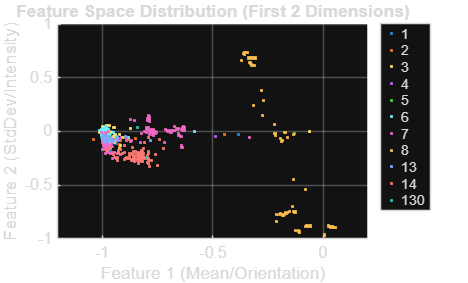


%scatter plot, plotted between mean and standard deviation features
figure('Name', 'Feature Separation', 'Color', 'w');
gscatter(Dataset_50HZ_Limited_Test_Final{:,1}, ...   
         Dataset_50HZ_Limited_Test_Final{:,2}, ...   
         Dataset_50HZ_Limited_Test_Final.label);     
title('Feature Space Distribution (First 2 Dimensions)');
xlabel('Feature 1 (Mean/Orientation)');
ylabel('Feature 2 (StdDev/Intensity)');
grid on;
legend('Location', 'bestoutside');


%% 5. Visualize & Predict Mobile Recorded Data

fprintf('\nRunning predictions on MATLAB Mobile recorded data...\n');


Running predictions on MATLAB Mobile recorded data...



% Ensure mobile_features is loaded
if ~exist('mobile_features','var')
    error('mobile_features not found. Please preprocess your MATLAB Mobile data first.');
end

% Measure inference time
tic;
mobile_predictions = myModel.predictFcn(mobile_features);
inference_time = toc;

fprintf('Inference on mobile data completed in %.4f seconds for %d samples.\n', inference_time, height(mobile_features));

Inference on mobile data completed in 0.0573 seconds for 20 samples.


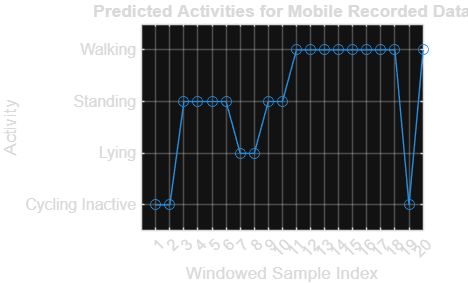


% Map numeric labels to descriptive activity names
labelMap = containers.Map( ...
    [1,2,3,4,5,6,7,8,13,14,130], ...   % numeric keys
    {'Walking','Running','Shuffling','Stairs Up','Stairs Down', ...
     'Standing','Sitting','Lying','Cycling Sit','Cycling Stand','Cycling Inactive'} ...
);

% Convert numeric predictions to string labels
mobile_predictions_str = arrayfun(@(x) labelMap(x), mobile_predictions, 'UniformOutput', false);
mobile_predictions_cat = categorical(mobile_predictions_str);

% If you have ground truth for mobile recording, use it to compare
if ismember('label', mobile_features.Properties.VariableNames)
    mobile_labels_str = arrayfun(@(x) labelMap(x), mobile_features.label, 'UniformOutput', false);
    mobile_labels_cat = categorical(mobile_labels_str);
else
    mobile_labels_cat = [];
end

%% 5a. Plot predictions over time
figure('Name', 'Mobile Data Predictions', 'Color', 'w');
plot(mobile_predictions_cat, 'o-');
title('Predicted Activities for Mobile Recorded Data');
xlabel('Windowed Sample Index');
ylabel('Activity');
grid on;
xticks(1:height(mobile_features));
xtickangle(45);


% Optionally overlay ground truth if available
if ~isempty(mobile_labels_cat)
    hold on;
    plot(mobile_labels_cat, 'x-');
    legend('Predicted','Ground Truth','Location','best');
end

%% 5b. Confusion matrix if ground truth available
if ~isempty(mobile_labels_cat)
    figure('Name','Mobile Data Confusion Matrix','Color','w');
    cm_mobile = confusionchart(mobile_labels_cat, mobile_predictions_cat);
    cm_mobile.Title = 'Confusion Matrix for Mobile Recorded Data';
    cm_mobile.RowSummary = 'row-normalized';
    cm_mobile.ColumnSummary = 'column-normalized';
end

fprintf('Visualization complete.\n');

Visualization complete.
